Boat Project: Rowan and Jacob

width = 0.0254*2;            % width  (m)
height = 0.06025;            % height (m)
length = 0.07*2;            % length (m)

% physical constants
wrho = 1000; % water density kg/m^3
g = 9.8;     % gravity m/s^2

dispratio = 0.25;    % ratio of boat displacement to max diplacement
CoM_offset = [0; 0;-0.005]; % Offset of the center of mass, e.g. using ballast


Npts = 100;                        % number of 1D spatial points (not a design variable; don't change)
xPoints = linspace(-width/2,width/2,Npts); % set of points in the x direction (horizontal)
yPoints = linspace(-length/2,length/2,Npts);
zPoints = linspace(0,height,Npts);      % set of points in the z direction (vertical)

[X, Y, Z] = meshgrid(xPoints,yPoints, zPoints); % create the meshgrid


global P insideBoat dV boatdisp wrho
P = [X(:)'; Y(:)'; Z(:)']; 

a = [];
insideBoat = zeros(size(P(1,:)));



for i = 1:1:Npts
    %get the height of the parabola section using sheer plane equation for
    %current "slice" / section of boat
    sheer_plane_height = sheer_plane_function(P(2,i));
    %get the width of the parabola section
    water_plane_width = hull_plane_function(P(2,i));
    %compute parabola "A" term
    ellipse_width = water_plane_width;
    ellipse_height = height - sheer_plane_height;
    
    %y = a(x-h)^2+k
    
    insideSlice = (P(2,:) == yPoints(i));
    
    t2 = (ellipse_height^2);
    t1 = -(t2) .* (P(1,:).^2);
    t3 = (ellipse_width^2);
    
    Z_bottom = -1 * sqrt((t1/t3) + t2) + height;
    
    %Z_bottom = parabola_width.*(P(1,:)).^2 + sheer_plane_height;
    Z_top = height;
    
    
    insideSection = (P(3,:) > Z_bottom) & (P(3,:) < Z_top);
    %scatter3(P(1,insideSection&insideSlice), P(2,insideSection&insideSlice), P(3,insideSection&insideSlice), ".k");
    insideBoat = insideBoat + (insideSection&insideSlice);
    

    

    
end
insideBoat = insideBoat > 0;

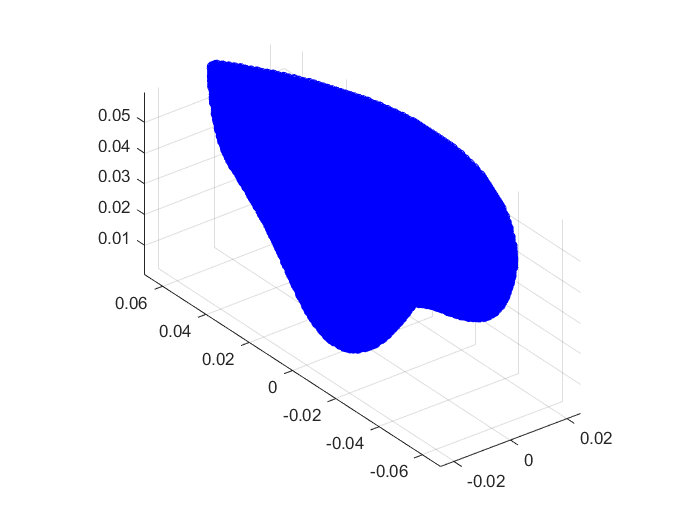


clf

scatter3(P(1,insideBoat), P(2,insideBoat), P(3,insideBoat), 'b')
axis equal

%function for the depth of the boar as viewd from the side: this is the
%crazy witch function thing

dx = xPoints(2)-xPoints(1); % delta x
dy = yPoints(2)-yPoints(1); % delta y
dz = zPoints(2)-zPoints(1); % delta z
dA = dx*dz;
dV= dx*dz*dy

dV = 4.4161e-10

test= sum(insideBoat)*dV*.2*1250

test = 0.0352

    
sum(P(3,insideBoat))*dV*.2*1250/test

ans = 0.0424


boatmasses = transpose(insideBoat)*wrho*dV;% find the water mass of each small section
maxdisp = sum(boatmasses)        % find the maximum displacement of the boat

maxdisp = 0.1410

boatdisp = dispratio*maxdisp     % set the displacement of the boat

boatdisp = 0.0352

CoD = P*boatmasses/maxdisp       % find the centroid of the boat consider inside boat????

CoD =    -0.0000
   -0.0000
    0.0424


P = P - CoD;                       % center the boat on the centroid
CoD = CoD - CoD;                   % update the centroid after centering
CoM = CoD + CoM_offset         % adjust the center of mass, e.g. for ballast

CoM =          0
         0
   -0.0050


dtheta = 1; % define the angle step
R = [cosd(dtheta) 0 -sind(dtheta);
  0 1 0;
  sind(dtheta) 0 cosd(dtheta)]

R =     0.9998         0   -0.0175
         0    1.0000         0
    0.0175         0    0.9998



j = 1; % set the counter
for theta = 0:dtheta:180% loop over the angles
    % Bound the waterline
    dmin = min(P(3, :)); % find the minimum z coordinate of the boat
    dmax = max(P(3, :)); % find the maximum z coordinate of the boat
    % Solve for the waterline of the rotated boat
    d = fzero(@waterline_error, [dmin, dmax]); % find the waterline d
% Analyze the boat
    underWater = (P(3,:) <= d)';
    underWaterAndInsideBoat = insideBoat & underWater';
    watermasses = underWaterAndInsideBoat*wrho*dV;
    watermass = sum(watermasses);
    CoB = P*watermasses'./watermass';
    % Store the results
    torque(j) = boatdisp * g * (CoB(1,1) - CoM(1,1)); % find the torque (N m)
    angle(j) = theta;                                 % record the angle (deg)

%     % Uncomment these lines to display a rotated boat;
%     % useful for undertanding, but slows down the computation
%     hold off
%     scatter(P(1,insideBoat),P(2,insideBoat),[],boatcolor), axis equal, axis([-max(W,H) max(W,H) -max(W,H) max(W,H)]), hold on
%     scatter(P(1,underWaterAndInsideBoat),P(2,underWaterAndInsideBoat),[],watercolor)
%     scatter(CoM(1,1), CoM(2,1), 1000, 'r.'); % plot the COM
%     scatter(CoB(1,1), CoB(2,1), 1000, 'k.'); % plot the COB
%     drawnow

    % Rotate the system
    P = R*P;     % rotate the boat by dtheta
    CoM = R*CoM; % rotate the center of mass too
    j = j + 1;   % update the counter
end

clf
plot(angle, torque)
xlabel('heel angle (degrees)')
ylabel('Torque (N m)')
min(torque)

ans = -0.0022

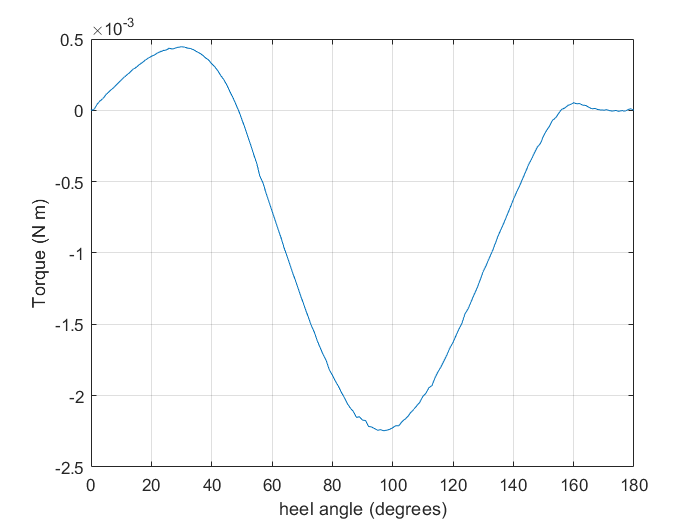

grid on

function res = sheer_plane_function(x)
res = zeros(size(x));
    if x < -0.04185 || x > 0.04185
        res = res + (1E10 .* x .^ 10) + 0.032;
    end
    if x >= -0.04185 && x <= 0.04185
        res = res + ((-1 * ((0.037^3.5) / (x.^2 + 0.037^(2.5)))) + 0.037);
    end  
end

%fucntion for width of boat as viewd from above
function res = hull_plane_function(x)
res = -5.17*(x^2) + 0.0254;
end

function res = waterline_error(d)
global P insideBoat dV boatdisp wrho

    underWater = (P(3,:) <= d)'; % test if each part of the meshgrid is under the water
    watermass = sum(underWater' & insideBoat) .* dV * wrho;
    res = watermass - boatdisp; % difference between boat displacement and water displacement
end
